% system
A = [0,1;0,0];
B1 = [3,1;-1,2];
B2 = [0;1];
% g = 2.248902;
g = 2.249;
% z(t)
C2 = [0,0;1,4;];
D2 = [-1;0];

% conditional test
C2'*D2 == 0

ans = 2×1 logical array
   1
   1


det(D2'*D2)

ans = 1

rank(ctrb(A,B2))

ans = 2

rank(obsv(A,C2))

ans = 2


% H_infinity control
Q = icare(A,B2,C2'*C2,D2'*D2,0,eye(2),(g.^-2).*B1*B1')

Q = 1.0e+04 *

    0.0894    0.3961
    0.3961    1.7554


K = -inv(D2'*D2)*B2'*Q

K = 1.0e+04 *

   -0.3961   -1.7554



% W(w->z)
syms s real;
W_s = (C2+D2*K)*inv(s*eye(2,2)-A-B2*K)*B1

$$W\_s = \begin{array}{l} \left(\begin{array}{cc} \frac{3266439485302683\,\left(274877906944\,s+4825302558872803\right)}{274877906944\,\sigma_{1}}-\frac{15761858097517157612304867474033}{274877906944\,\sigma_{1}}-\frac{4825302558872803\,s}{\sigma_{1}} & \frac{1088813161767561\,\left(274877906944\,s+4825302558872803\right)}{274877906944\,\sigma_{1}}-\frac{5253254354245479796649018856315}{274877906944\,\sigma_{1}}+\frac{9650605117745606\,s}{\sigma_{1}}\\ \frac{3\,\left(274877906944\,s+4825302558872803\right)}{\sigma_{1}}-\frac{13066032819117676}{\sigma_{1}}-\frac{1099511627776\,s}{\sigma_{1}} & \frac{274877906944\,s+4825302558872803}{\sigma_{1}}-\frac{4354702891256356}{\sigma_{1}}+\frac{2199023255552\,s}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=274877906944\,s^{2}+4825302558872803\,s+1088813161767561 \end{array}$$

[N11, D11] = numden(W_s(1,1));
[N12, D12] = numden(W_s(1,2));
[N21, D21] = numden(W_s(2,1));
[N22, D22] = numden(W_s(2,2));
WN11  = coeffs(N11, 'All');
WD11  = coeffs(D11, 'All');
WN12  = coeffs(N12, 'All');
WD12  = coeffs(D12, 'All');
WN21  = coeffs(N21, 'All');
WD21  = coeffs(D21, 'All');
WN22  = coeffs(N22, 'All');
WD22  = coeffs(D22, 'All');

W = [
    tf(double(WN11), double(WD11)), tf(double(WN12), double(WD12));
    tf(double(WN21), double(WD21)), tf(double(WN22), double(WD22));
    ]

W =
 
  From input 1 to output...
              -1.559e15 s - 1.089e15
   1:  ------------------------------------
       2.749e11 s^2 + 4.825e15 s + 1.089e15
 
              -2.749e11 s + 1.41e15
   2:  ------------------------------------
       2.749e11 s^2 + 4.825e15 s + 1.089e15
 
  From input 2 to output...
              1.074e16 s + 2.178e15
   1:  ------------------------------------
       2.749e11 s^2 + 4.825e15 s + 1.089e15
 
              2.474e12 s + 4.706e14
   2:  ------------------------------------
       2.749e11 s^2 + 4.825e15 s + 1.089e15
 
Continuous-time transfer function.




% H_2 norm of transfer fuction
h_2 = norm(W)

h_2 = 210.7002


% H_inf norm of transfer fuction
h_inf = getPeakGain(W)

h_inf = 2.2490

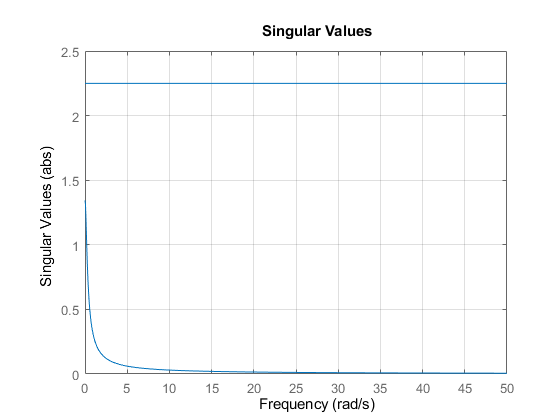


% ampW = bodeplot(W);
% setoptions(ampW,'FreqScale','linear','MagUnits','abs','Grid','on','PhaseVisible','off','IOGrouping','all');
% xlim([0 50]);

sinValW = sigmaplot(W);
setoptions(sinValW,'FreqScale','linear','MagUnits','abs','Grid','on');
xlim([0 50]);

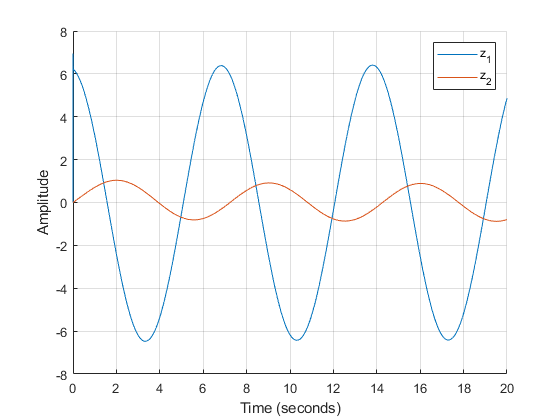


figure; %входные воздействия
grid on;
hold on;
plot(out.z.Time, out.z.Data(:,1))
plot(out.z.Time, out.z.Data(:,2))
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("z_1", "z_2")

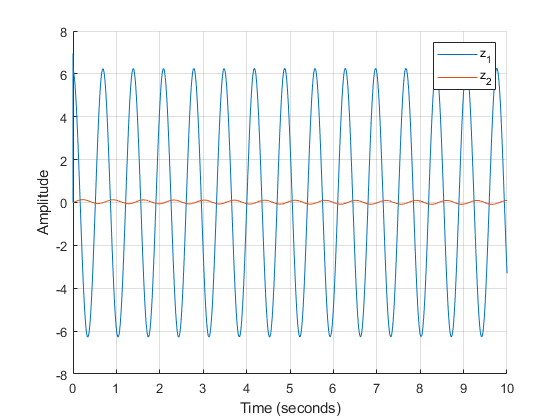

figure; %входные воздействия
grid on;
hold on;
plot(out.z1.Time, out.z1.Data(:,1))
plot(out.z1.Time, out.z1.Data(:,2))
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("z_1", "z_2")
xlim([0 10])